data = readtable('C:\Users\SUDARSHAN\OneDrive\Documents\COLLAGE\SEMISTER-2\MATHS\maths_pca\TCGA_LAML_PCA_READY.csv');


% we are converting the dataset into numeric matrix 
X = table2array(data);

% we are standeredizing here 
X = zscore(X);

%  mean is being centered
X_centered = X - mean(X);

% creating a covariance matrix
C = cov(X_centered)

C =     1.0000   -0.9998    0.9998    0.1987   -0.0584    0.0257   -0.0028   -0.0500    0.0508
   -0.9998    1.0000   -1.0000   -0.1973    0.0612   -0.0259    0.0042    0.0466   -0.0484
    0.9998   -1.0000    1.0000    0.1973   -0.0612    0.0259   -0.0042   -0.0466    0.0484
    0.1987   -0.1973    0.1973    1.0000    0.0168   -0.1552    0.1331    0.0584   -0.0867
   -0.0584    0.0612   -0.0612    0.0168    1.0000   -0.1516    0.1418   -0.0427    0.0049
    0.0257   -0.0259    0.0259   -0.1552   -0.1516    1.0000   -0.1394    0.0352   -0.0325
   -0.0028    0.0042   -0.0042    0.1331    0.1418   -0.1394    1.0000   -0.1757    0.0220
   -0.0500    0.0466   -0.0466    0.0584   -0.0427    0.0352   -0.1757    1.0000   -0.6755
    0.0508   -0.0484    0.0484   -0.0867    0.0049   -0.0325    0.0220   -0.6755    1.0000


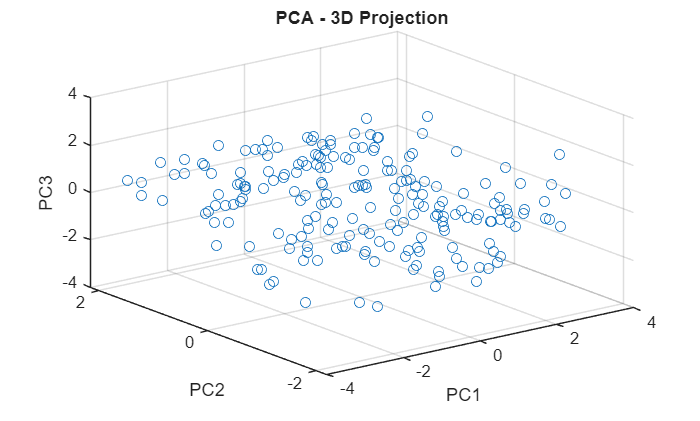


% doing eigen decamposition 
[V, D] = eig(C);

% sorting eigen values
[eigenvalues, idx] = sort(diag(D), 'descend');
V = V(:, idx);

% choosing number of componentes 
k = 3;
V_k = V(:, 1:k);

% projecting the data
X_manual = X_centered * V_k;

% plotting the graph 
figure;
scatter3(X_manual(:,1), X_manual(:,2), X_manual(:,3));
xlabel('PC1');
ylabel('PC2');
zlabel('PC3');
title('PCA - 3D Projection');
grid on;

data = readtable('C:\Users\SUDARSHAN\OneDrive\Documents\COLLAGE\SEMISTER-2\MATHS\maths_pca\TCGA_LAML_PCA_READY.csv');

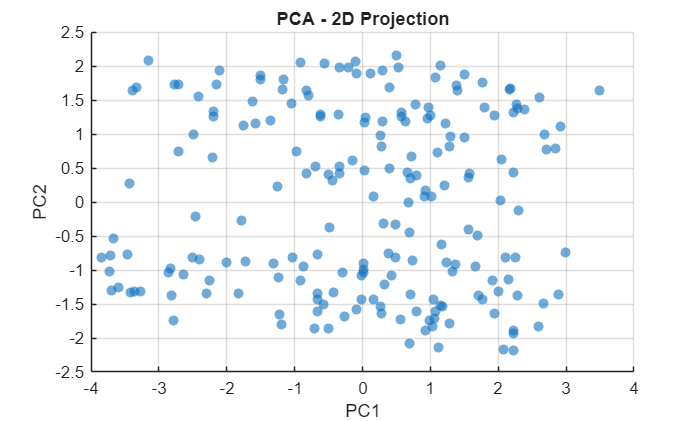


% we are converting the dataset into numeric matrix 
X = table2array(data);

% we are standeredizing here 
X = zscore(X);

%  mean is being centered
X_centered = X - mean(X);

% creating a covariance matrix
C = cov(X_centered);

% doing eigen decamposition 
[V, D] = eig(C);

% sorting eigen values
[eigenvalues, idx] = sort(diag(D), 'descend');
V = V(:, idx);

k2 = 2;
V_k2 = V(:, 1:k2);
X_2D = X_centered * V_k2;

figure;
scatter(X_2D(:,1), X_2D(:,2), 'filled', 'MarkerFaceAlpha', 0.6);
xlabel('PC1');
ylabel('PC2');
title('PCA - 2D Projection');
grid on;

data = readtable('C:\Users\SUDARSHAN\OneDrive\Documents\COLLAGE\SEMISTER-2\MATHS\maths_pca\TCGA_LAML_PCA_READY.csv');

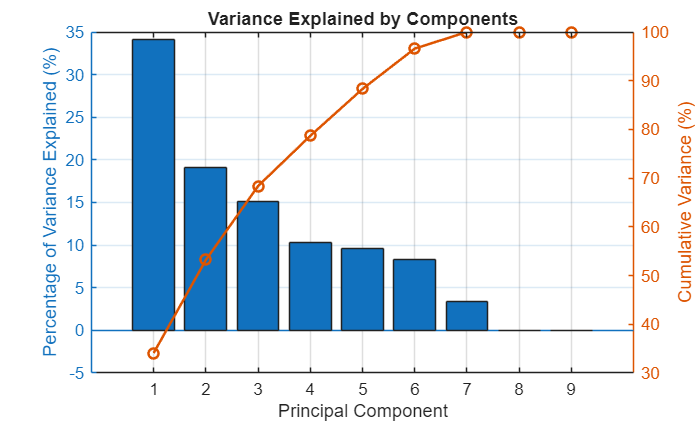


% we are converting the dataset into numeric matrix 
X = table2array(data);

% we are standeredizing here 
X = zscore(X);

%  mean is being centered
X_centered = X - mean(X);

% creating a covariance matrix
C = cov(X_centered);

% doing eigen decamposition 
[V, D] = eig(C);

% sorting eigen values
[eigenvalues, idx] = sort(diag(D), 'descend');
V = V(:, idx);

explained_variance = eigenvalues / sum(eigenvalues) * 100;
cumulative_variance = cumsum(explained_variance);

figure;
subplot(1,1,1);
yyaxis left
bar(explained_variance);
ylabel('Percentage of Variance Explained (%)');
yyaxis right
plot(cumulative_variance, '-o', 'LineWidth', 1.5);
ylabel('Cumulative Variance (%)');
xlabel('Principal Component');
title('Variance Explained by Components');
grid on;

data = readtable('C:\Users\SUDARSHAN\OneDrive\Documents\COLLAGE\SEMISTER-2\MATHS\maths_pca\TCGA_LAML_PCA_READY.csv');


% we are converting the dataset into numeric matrix 
X = table2array(data);

% we are standeredizing here 
X = zscore(X);

%  mean is being centered
X_centered = X - mean(X);

% creating a covariance matrix
C = cov(X_centered)

C =     1.0000   -0.9998    0.9998    0.1987   -0.0584    0.0257   -0.0028   -0.0500    0.0508
   -0.9998    1.0000   -1.0000   -0.1973    0.0612   -0.0259    0.0042    0.0466   -0.0484
    0.9998   -1.0000    1.0000    0.1973   -0.0612    0.0259   -0.0042   -0.0466    0.0484
    0.1987   -0.1973    0.1973    1.0000    0.0168   -0.1552    0.1331    0.0584   -0.0867
   -0.0584    0.0612   -0.0612    0.0168    1.0000   -0.1516    0.1418   -0.0427    0.0049
    0.0257   -0.0259    0.0259   -0.1552   -0.1516    1.0000   -0.1394    0.0352   -0.0325
   -0.0028    0.0042   -0.0042    0.1331    0.1418   -0.1394    1.0000   -0.1757    0.0220
   -0.0500    0.0466   -0.0466    0.0584   -0.0427    0.0352   -0.1757    1.0000   -0.6755
    0.0508   -0.0484    0.0484   -0.0867    0.0049   -0.0325    0.0220   -0.6755    1.0000



% doing eigen decamposition 
[V, D] = eig(C);

% sorting eigen values
[eigenvalues, idx] = sort(diag(D), 'descend');
V = V(:, idx);

explained = (eigenvalues / sum(eigenvalues)) * 100;
cumulative = cumsum(explained);


k = 5;
disp(['Variance retained = ', num2str(cumulative(k)), '%']);

Variance retained = 88.3082%


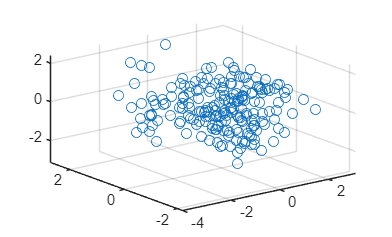


V_k = V(:, 1:k);

% projecting the data
X_manual = X_centered * V_k;

% plotting the graph 
figure;
scatter3(X_manual(:,3), X_manual(:,4), X_manual(:,5))
grid on;